%PARTE DE ESTADISTICA COMPUTACIONAL

F = readtable('my2024-fuel-consumption-ratings.csv');

head(F,10 )

    ModelYear         Make                  Model                        VehicleClass                EngineSize_L_    Cylinders    Transmission    FuelType    City_L_100Km_    Highway_L_100Km_    Combined_L_100Km_    Combined_mpg_    CO2Emissions_g_km_    CO2Rating    SmogRating
    _________    ______________    _______________________    ___________________________________    _____________    _________    ____________    ________    _____________    ________________    _________________    _____________    __________________<

categorias = unique(F.VehicleClass);

mediaPorClase = [];
medianaPorClase = [];
desviacionStdPorClase = [];
curtosisPorClase = []; 
asimetriaPorClase = []; 
cuartilesPorClase = []; 

for i = 1:length(categorias)
    clase = categorias{i};
    consumoPorClase = F.Combined_L_100Km_(strcmp(F.VehicleClass, clase));
    mediaPorClase(i) = mean(consumoPorClase);
    medianaPorClase(i) = median(consumoPorClase);
    desviacionStdPorClase(i) = std(consumoPorClase);
    curtosisPorClase(i) = kurtosis(consumoPorClase); 
    asimetriaPorClase(i) = skewness(consumoPorClase); 
    cuartilesPorClase(i, :) = quantile(consumoPorClase, [0.25 0.5 0.75]);
end

tabla_completa = table(categorias, mediaPorClase', medianaPorClase', desviacionStdPorClase', ...
    cuartilesPorClase(:,1), cuartilesPorClase(:,2), cuartilesPorClase(:,3), ...
    curtosisPorClase', asimetriaPorClase', ...
    'VariableNames', {'Clase', 'Media', 'Mediana', 'DesviacionStd', 'Cuartil1', 'Cuartil2', 'Cuartil3', 'Curtosis', 'Asimetria'});

disp(tabla_completa);

                   Clase                   Media     Mediana    DesviacionStd    Cuartil1    Cuartil2    Cuartil3    Curtosis    Asimetria
    ___________________________________    ______    _______    _____________    ________    ________    ________    ________    _________

    {'Compact'                        }    8.9404       8.8         2.1504           7.2        8.8         10.2      2.4879       0.1443 
    {'Full-size'                      }    10.647       9.8         3.3607             8        9.8         12.1      2.3728      0.63639 
    {'Mid-size'                       }    9.3659      9.05         2.5692           7.7       9.05         11.1      3.0782      0.54363

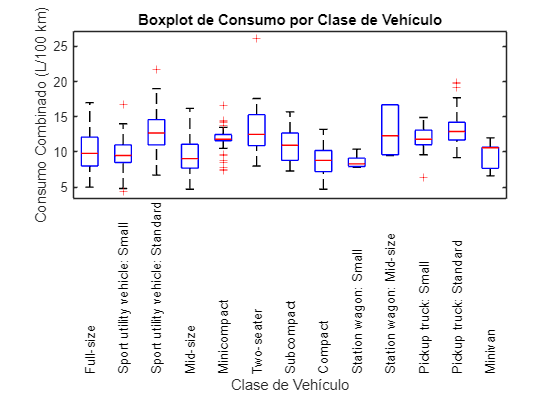

figure;
boxplot(F.Combined_L_100Km_, F.VehicleClass, 'LabelOrientation', 'inline');
title('Boxplot de Consumo por Clase de Vehículo');
xlabel('Clase de Vehículo');
ylabel('Consumo Combinado (L/100 km)');

categorias = unique(F.VehicleClass);
conteoObservaciones = zeros(length(categorias), 1);

for i = 1:length(categorias)
    clase = categorias{i};
    conteoObservaciones(i) = sum(strcmp(F.VehicleClass, clase));
end

tabla_conteo = table(categorias, conteoObservaciones, ...
    'VariableNames', {'Clase', 'NumeroObservaciones'});

disp(tabla_conteo);

                   Clase                   NumeroObservaciones
    ___________________________________    ___________________

    {'Compact'                        }             47        
    {'Full-size'                      }             34        
    {'Mid-size'                       }             82        
    {'Minicompact'                    }             47        
    {'Minivan'                        }              7        
    {'Pickup truck: Small'            }             19        
    {'Pickup truck: Standard'         }             73        
    {'Sport utility vehicle: Small'   }            181        
    {'Sport utility vehicle: Standard'}            130        
    {'Station wagon: Mid-size'        }              6        
    {'Station wagon: Small'           }             11        
    {'Subcompact'                     }             58        
    {'Two-seater'                     }          

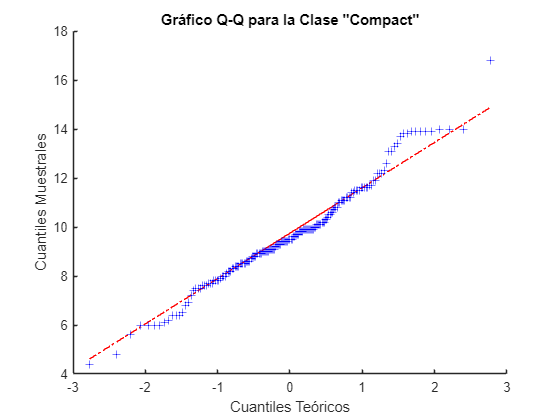

clase_compact = F.Combined_L_100Km_(strcmp(F.VehicleClass, 'Sport utility vehicle: Small'));
figure;
qqplot(clase_compact);
title('Gráfico Q-Q para la Clase "Compact"');
xlabel('Cuantiles Teóricos');
ylabel('Cuantiles Muestrales');


makeCountryMap = containers.Map(...
    {'Acura', 'Alfa Romeo', 'Aston Martin', 'Audi', 'BMW', 'Bentley', 'Bugatti', ...
    'Buick', 'Cadillac', 'Chevrolet', 'Chrysler', 'Dodge', 'Ferrari', 'Ford', ...
    'GMC', 'Genesis', 'Honda', 'Hyundai', 'Infiniti', 'Jaguar', 'Jeep', 'Kia', ...
    'Lamborghini', 'Land Rover', 'Lexus', 'Lincoln', 'MINI', 'Maserati', 'Mazda', ...
    'Mercedes-Benz', 'Mitsubishi', 'Nissan', 'Porsche', 'Ram', 'Rolls-Royce', ...
    'Subaru', 'Toyota', 'Volkswagen', 'Volvo'}, ...
    {'Japón', 'Italia', 'Reino Unido', 'Alemania', 'Alemania', 'Reino Unido', ...
    'Francia', 'Estados Unidos', 'Estados Unidos', 'Estados Unidos', 'Estados Unidos', ...
    'Estados Unidos', 'Italia', 'Estados Unidos', 'Estados Unidos', 'Corea del Sur', ...
    'Japón', 'Corea del Sur', 'Japón', 'Reino Unido', 'Estados Unidos', 'Corea del Sur', ...
    'Italia', 'Reino Unido', 'Japón', 'Estados Unidos', 'Reino Unido', 'Italia', 'Japón', ...
    'Alemania', 'Japón', 'Japón', 'Alemania', 'Estados Unidos', 'Reino Unido', ...
    'Japón', 'Japón', 'Alemania', 'Suecia'});

countryData = cell(height(F), 1);

for i = 1:height(F)
    make = F.Make{i}; 
    if makeCountryMap.isKey(make)
        countryData{i} = makeCountryMap(make);
    else
        countryData{i} = 'Desconocido'; 
    end
end
F.Country = countryData;
head(F,10)

    ModelYear         Make                  Model                        VehicleClass                EngineSize_L_    Cylinders    Transmission    FuelType    City_L_100Km_    Highway_L_100Km_    Combined_L_100Km_    Combined_mpg_    CO2Emissions_g_km_    CO2Rating    SmogRating     Country  
    _________    ______________    _______________________    ___________________________________    _____________    _________    ____________    ________    _____________    ________________    _________________    _____________

uniqueCountries = unique(F.Country);
disp(uniqueCountries);

    {'Alemania'      }
    {'Corea del Sur' }
    {'Estados Unidos'}
    {'Francia'       }
    {'Italia'        }
    {'Japón'         }
    {'Reino Unido'   }
    {'Suecia'        }



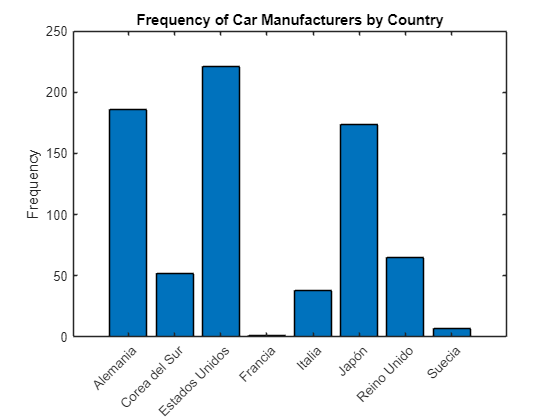

countryCounts = groupsummary(F, 'Country', 'IncludeMissing', false);
figure;
bar(countryCounts.GroupCount);
xticks(1:length(countryCounts.Country));
xticklabels(countryCounts.Country);
xtickangle(45);
ylabel('Frequency');
title('Frequency of Car Manufacturers by Country');

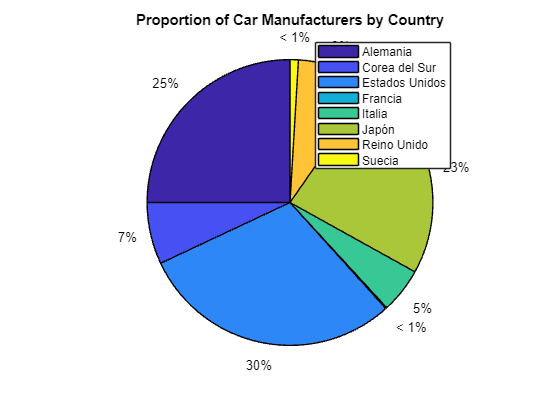

figure;
pie(countryCounts.GroupCount);
legend(countryCounts.Country);
title('Proportion of Car Manufacturers by Country');

%PARTE DE INFERENCIA ESTADISTICA 

%Distribuciones y contrastes de bondad de ajuste

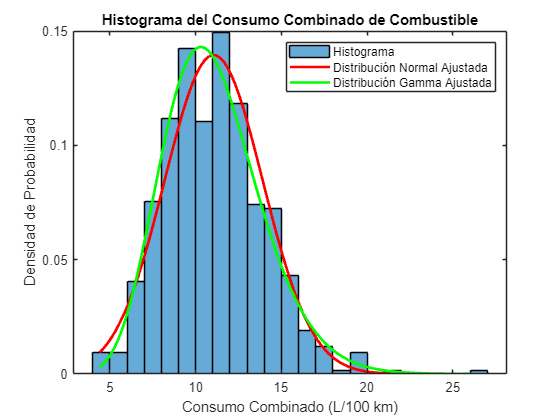

histogram(F.Combined_L_100Km_, 'Normalization', 'pdf');
title('Histograma del Consumo Combinado de Combustible');
xlabel('Consumo Combinado (L/100 km)');
ylabel('Densidad de Probabilidad');

mu = mean(F.Combined_L_100Km_);
sigma = std(F.Combined_L_100Km_);

hold on;
x = linspace(min(F.Combined_L_100Km_), max(F.Combined_L_100Km_), 100);
y = normpdf(x, mu, sigma);
plot(x, y, 'r', 'LineWidth', 2);
legend('Histograma', 'Distribución Normal Ajustada');
hold off;
paramGamma = gamfit(F.Combined_L_100Km_);
shape = paramGamma(1);
scale = paramGamma(2);

hold on;
y_gamma = gampdf(x, shape, scale);
plot(x, y_gamma, 'g', 'LineWidth', 2);
legend('Histograma', 'Distribución Normal Ajustada', 'Distribución Gamma Ajustada');
hold off;

combined_consumption = F.Combined_L_100Km_;
combined_consumption = combined_consumption(~isnan(combined_consumption));

mu = mean(combined_consumption);
sigma = std(combined_consumption);
fprintf('Parámetros estimados para la distribución normal:\n');

Parámetros estimados para la distribución normal:


fprintf('Media (mu): %.4f\n', mu);

Media (mu): 11.0504


fprintf('Desviación estándar (sigma): %.4f\n', sigma);

Desviación estándar (sigma): 2.8595


paramGamma = gamfit(combined_consumption);
shape = paramGamma(1);
scale = paramGamma(2);
fprintf('Parámetros estimados para la distribución gamma:\n');

Parámetros estimados para la distribución gamma:


fprintf('Forma (shape): %.4f\n', shape);

Forma (shape): 14.8260


fprintf('Escala (scale): %.4f\n', scale);

Escala (scale): 0.7453


num_bins = 10;
[observed_freq, bin_edges] = histcounts(combined_consumption, num_bins);

expected_freq_normal = zeros(1, num_bins);
for i = 1:num_bins
    p = normcdf(bin_edges(i + 1), mu, sigma) - normcdf(bin_edges(i), mu, sigma);
    expected_freq_normal(i) = p * length(combined_consumption);
end

expected_freq_gamma = zeros(1, num_bins);
for i = 1:num_bins
    p = gamcdf(bin_edges(i + 1), shape, scale) - gamcdf(bin_edges(i), shape, scale);
    expected_freq_gamma(i) = p * length(combined_consumption);
end

disp('Frecuencias Observadas:');

Frecuencias Observadas:


disp(observed_freq);

    23   129   210   225   112    35     8     1     0     1



disp('Frecuencias Esperadas (Normal):');

Frecuencias Esperadas (Normal):


disp(expected_freq_normal);

   30.8697  109.6743  210.7631  219.3815  123.6969   37.7348    6.2136    0.5506    0.0262    0.0007



disp('Frecuencias Esperadas (Gamma):');

Frecuencias Esperadas (Gamma):


disp(expected_freq_gamma);

   21.5200  127.5718  232.6242  202.2310  106.4489   39.1157   10.9841    2.5044    0.4837    0.0816



chi2_stat_normal = sum((observed_freq - expected_freq_normal).^2 ./ expected_freq_normal);
df_normal = num_bins - 1 - 2; 
p_value_normal = 1 - chi2cdf(chi2_stat_normal, df_normal);
fprintf('Resultados del contraste Chi-cuadrado para la distribución normal:\n');

Resultados del contraste Chi-cuadrado para la distribución normal:


fprintf('Chi2 Estadístico: %.2f\n', chi2_stat_normal);

Chi2 Estadístico: 1509.88


fprintf('Grados de Libertad: %d\n', df_normal);

Grados de Libertad: 7


fprintf('p-valor: %.4f\n', p_value_normal);

p-valor: 0.0000


chi2_stat_gamma = sum((observed_freq - expected_freq_gamma).^2 ./ expected_freq_gamma);
df_gamma = num_bins - 1 - 2; 
p_value_gamma = 1 - chi2cdf(chi2_stat_gamma, df_gamma);
fprintf('Resultados del contraste Chi-cuadrado para la distribución gamma:\n');

Resultados del contraste Chi-cuadrado para la distribución gamma:


fprintf('Chi2 Estadístico: %.2f\n', chi2_stat_gamma);

Chi2 Estadístico: 18.14


fprintf('Grados de Libertad: %d\n', df_gamma);

Grados de Libertad: 7


fprintf('p-valor: %.4f\n', p_value_gamma);

p-valor: 0.0114


combined_consumption = combined_consumption(~isnan(combined_consumption));


%Estimación paramétrica


combined_consumption = F.Combined_L_100Km_;
combined_consumption = combined_consumption(~isnan(combined_consumption));

mu_true = mean(combined_consumption);
sigma_true = std(combined_consumption);

nSim = 1000;
n = length(combined_consumption);

mu_sim = zeros(nSim, 1);
sigma_sim = zeros(nSim, 1);

rng('default');  
for i = 1:nSim
    sample = datasample(combined_consumption, n);  
    mu_sim(i) = mean(sample);
    sigma_sim(i) = std(sample);
end

sesgo_mu = mean(mu_sim) - mu_true;
sesgo_sigma = mean(sigma_sim) - sigma_true;

eficiencia_mu = var(mu_sim);
eficiencia_sigma = var(sigma_sim);

fprintf('Sesgo del estimador de la media: %.4f\n', sesgo_mu);

Sesgo del estimador de la media: -0.0046


fprintf('Sesgo del estimador de la varianza: %.4f\n', sesgo_sigma);

Sesgo del estimador de la varianza: -0.0039


fprintf('Eficiencia del estimador de la media (varianza): %.4f\n', eficiencia_mu);

Eficiencia del estimador de la media (varianza): 0.0106


fprintf('Eficiencia del estimador de la varianza (varianza): %.4f\n', eficiencia_sigma);

Eficiencia del estimador de la varianza (varianza): 0.0076


%Proponer modelos de regresión lineal (o no lineal) 

F = rmmissing(F);

X = [F.EngineSize_L_, F.Cylinders, F.CO2Emissions_g_km_, dummyvar(categorical(F.Country))];

corrMatrix = corr(X);
disp(corrMatrix);

    1.0000    0.9172    0.7845   -0.0705   -0.1721    0.2524    0.1422    0.0939   -0.2103    0.1070   -0.0831
    0.9172    1.0000    0.7894    0.0429   -0.1776    0.1009    0.2041    0.1946   -0.2711    0.1865   -0.0791
    0.7845    0.7894    1.0000    0.0704   -0.2247    0.2836    0.1968    0.1632   -0.4004    0.1055   -0.0647
   -0.0705    0.0429    0.0704    1.0000   -0.1583   -0.3753   -0.0212   -0.1339   -0.3190   -0.1786   -0.0563
   -0.1721   -0.1776   -0.2247   -0.1583    1.0000   -0.1782   -0.0101   -0.0636   -0.1515   -0.0848   -0.0267
    0.2524    0.1009    0.2836   -0.3753   -0.1782    1.0000   -0.0238   -0.1508   -0.3592   -0.2011   -0.0634
    0.1422    0.2041    0.1968   -0.0212   -0.0101   -0.0238    1.0000   -0.0085   -0.0203   -0.0114   -0.0036
    0.0939    0.1946    0.1632   -0.1339   -0.0636   -0.1508   -0.0085    1.0000   -0.1282   -0.0718   -0.0226
   -0.2103   -0.2711   -0.4004   -0.3190   -0.1515   -0.3592   -0.0203   -0.1282    1.0000   -0.1709   -0.0538
 

threshold = 0.9;
toRemove = [];
for i = 1:size(corrMatrix, 1)
    for j = i+1:size(corrMatrix, 2)
        if abs(corrMatrix(i, j)) > threshold
            toRemove = [toRemove, j];
        end
    end
end
X_reduced = X;
X_reduced(:, unique(toRemove)) = [];

Y = F.Combined_L_100Km_;

mdl_reduced = fitlm(X_reduced, Y);

disp(mdl_reduced);

Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10

Estimated Coefficients:
                   Estimate         SE          tStat        pValue  
                   _________    __________    _________    __________

    (Intercept)      0.18561       0.59015      0.31452       0.75321
    x1               0.13957      0.026225       5.3221    1.3645e-07
    x2              0.040786    0.00056438       72.267             0
    x3             -0.079061       0.55966     -0.14127        0.8877
    x4               -0.1562       0.56906     -0.27448       0.78379
    x5              -0.11971       0.55804     -0.21451       0.83021
    x6                     0             0          NaN           NaN
   

k = 10;
cvErrors_reduced = zeros(k, 1);
cv = cvpartition(length(Y), 'KFold', k);

for i = 1:k
    trainIdx = cv.training(i);
    testIdx = cv.test(i);
    mdl_reduced = fitlm(X_reduced(trainIdx, :), Y(trainIdx));
    Y_pred = predict(mdl_reduced, X_reduced(testIdx, :));
    cvErrors_reduced(i) = mean((Y(testIdx) - Y_pred).^2);
end


cvError_reduced = mean(cvErrors_reduced);
fprintf('Error de predicción promedio (MSE) con variables reducidas: %.4f\n', cvError_reduced);

Error de predicción promedio (MSE) con variables reducidas: 0.2978


%Intervalos de confianza

data = F.Combined_L_100Km_;

alpha = 0.05;
n = length(data);
mu = mean(data);
sigma = std(data);

z = norminv(1 - alpha/2);
CI_mu_teorico = [mu - z * sigma / sqrt(n), mu + z * sigma / sqrt(n)];

chi2_lower = chi2inv(alpha/2, n - 1);
chi2_upper = chi2inv(1 - alpha/2, n - 1);
CI_var_teorico = [(n-1) * sigma^2 / chi2_upper, (n-1) * sigma^2 / chi2_lower];

nBoot = 1000;
bootstat_mu = bootstrp(nBoot, @mean, data);
CI_mu_bootstrap = prctile(bootstat_mu, [2.5, 97.5]);

bootstat_var = bootstrp(nBoot, @var, data);
CI_var_bootstrap = prctile(bootstat_var, [2.5, 97.5]);

fprintf('Intervalo de confianza teórico para la media: [%.4f, %.4f]\n', CI_mu_teorico);

Intervalo de confianza teórico para la media: [10.8449, 11.2559]


fprintf('Intervalo de confianza Bootstrap para la media: [%.4f, %.4f]\n', CI_mu_bootstrap);

Intervalo de confianza Bootstrap para la media: [10.8464, 11.2449]


fprintf('Intervalo de confianza teórico para la varianza: [%.4f, %.4f]\n', CI_var_teorico);

Intervalo de confianza teórico para la varianza: [7.4052, 9.0765]


fprintf('Intervalo de confianza Bootstrap para la varianza: [%.4f, %.4f]\n', CI_var_bootstrap);

Intervalo de confianza Bootstrap para la varianza: [7.2460, 9.2894]


%Contraste de hipotesis

combined_consumption = F.Combined_L_100Km_;
combined_consumption = combined_consumption(~isnan(combined_consumption));

mu_hipotetico = 11;

[h, p, ci, stats] = ttest(combined_consumption, mu_hipotetico);

fprintf('Resultados de la prueba t para una muestra:\n');

Resultados de la prueba t para una muestra:


fprintf('Estadístico t: %.4f\n', stats.tstat);

Estadístico t: 0.4808


fprintf('p-valor: %.4f\n', p);

p-valor: 0.6308


fprintf('Intervalo de confianza: [%.4f, %.4f]\n', ci);

Intervalo de confianza: [10.8446, 11.2562]


fprintf('Rechazar H0: %d\n', h);

Rechazar H0: 0


var_hipotetica = 8;
n = length(combined_consumption);
var_muestral = var(combined_consumption);

chi2_stat = (n - 1) * var_muestral / var_hipotetica;

p_valor_chi2 = 2 * min(chi2cdf(chi2_stat, n - 1), 1 - chi2cdf(chi2_stat, n - 1));

fprintf('Estadístico Chi-cuadrado: %.4f\n', chi2_stat);

Estadístico Chi-cuadrado: 759.4275


fprintf('p-valor: %.4f\n', p_valor_chi2);

p-valor: 0.6597


%Funcion de densidad no parametrice de variable numerica

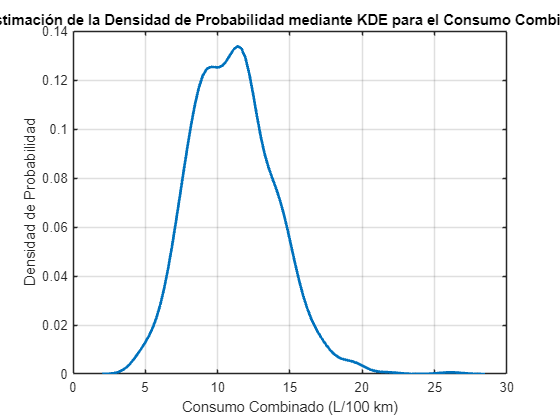

combined_consumption = F.Combined_L_100Km_;
combined_consumption = combined_consumption(~isnan(combined_consumption));

[f, xi] = ksdensity(combined_consumption);

figure;
plot(xi, f, 'LineWidth', 2);
xlabel('Consumo Combinado (L/100 km)');
ylabel('Densidad de Probabilidad');
title('Estimación de la Densidad de Probabilidad mediante KDE para el Consumo Combinado');
grid on;

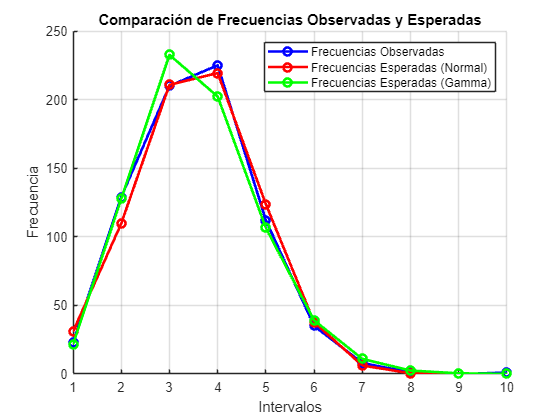

% Frecuencias observadas y esperadas para la distribución Normal
observed_freq = [23, 129, 210, 225, 112, 35, 8, 1, 0, 1];
expected_freq_normal = [30.8697, 109.6743, 210.7631, 219.3815, 123.6969, 37.7348, 6.2136, 0.5506, 0.0262, 0.0007];

% Frecuencias esperadas para la distribución Gamma
expected_freq_gamma = [21.5200, 127.5718, 232.6242, 202.2310, 106.4489, 39.1157, 10.9841, 2.5044, 0.4837, 0.0816];

% Crear el gráfico de líneas superpuestas
figure;
hold on;

% Gráfico de líneas para frecuencias observadas
plot(1:10, observed_freq, '-ob', 'LineWidth', 2, 'DisplayName', 'Frecuencias Observadas');

% Gráfico de líneas para frecuencias esperadas (Normal)
plot(1:10, expected_freq_normal, '-or', 'LineWidth', 2, 'DisplayName', 'Frecuencias Esperadas (Normal)');

% Gráfico de líneas para frecuencias esperadas (Gamma)
plot(1:10, expected_freq_gamma, '-og', 'LineWidth', 2, 'DisplayName', 'Frecuencias Esperadas (Gamma)');

% Configuración de la gráfica
xlabel('Intervalos');
ylabel('Frecuencia');
title('Comparación de Frecuencias Observadas y Esperadas');
legend show;
grid on;
hold off;

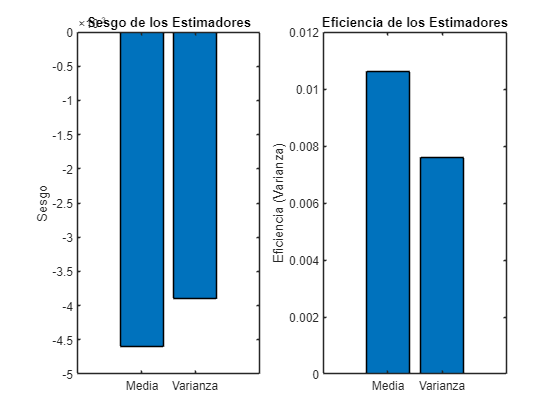

% Valores de sesgo y eficiencia
sesgo_media = -0.0046;
sesgo_varianza = -0.0039;
eficiencia_media = 0.0106;
eficiencia_varianza = 0.0076;

% Datos para el gráfico de barras
valores_sesgo = [sesgo_media, sesgo_varianza];
valores_eficiencia = [eficiencia_media, eficiencia_varianza];
categorias = {'Media', 'Varianza'};

% Crear gráfico de barras para sesgo
figure;
subplot(1, 2, 1);
bar(valores_sesgo);
set(gca, 'XTickLabel', categorias);
ylabel('Sesgo');
title('Sesgo de los Estimadores');

% Crear gráfico de barras para eficiencia
subplot(1, 2, 2);
bar(valores_eficiencia);
set(gca, 'XTickLabel', categorias);
ylabel('Eficiencia (Varianza)');
title('Eficiencia de los Estimadores');

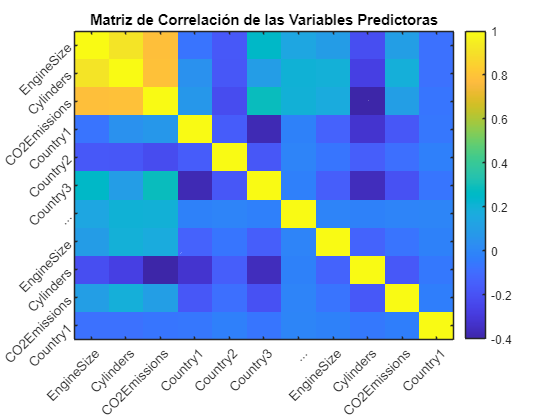

% Matriz de correlación
corrMatrix = corr(X);
figure;
imagesc(corrMatrix);
colorbar;
title('Matriz de Correlación de las Variables Predictoras');
set(gca, 'XTick', 1:size(X, 2), 'XTickLabel', {'EngineSize', 'Cylinders', 'CO2Emissions', 'Country1', 'Country2', 'Country3', '...'});
set(gca, 'YTick', 1:size(X, 2), 'YTickLabel', {'EngineSize', 'Cylinders', 'CO2Emissions', 'Country1', 'Country2', 'Country3', '...'});
xtickangle(45);
ytickangle(45);

% Resultados de la validación cruzada
k = 10;
cvErrors = zeros(k, 1);

for i = 1:k
    trainIdx = cv.training(i);
    testIdx = cv.test(i);
    mdl = fitlm(X(trainIdx, :), Y(trainIdx));
    Y_pred = predict(mdl, X(testIdx, :));
    cvErrors(i) = mean((Y(testIdx) - Y_pred).^2);
end

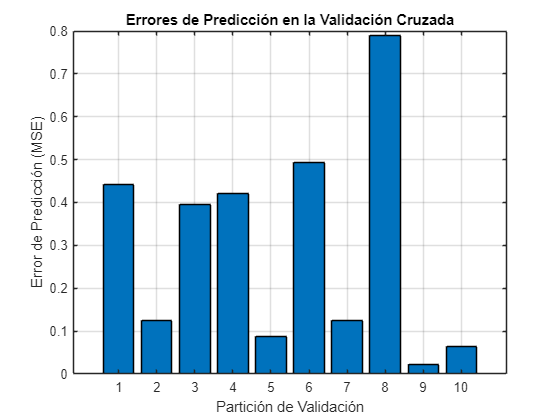


figure;
bar(cvErrors);
title('Errores de Predicción en la Validación Cruzada');
xlabel('Partición de Validación');
ylabel('Error de Predicción (MSE)');
grid on;

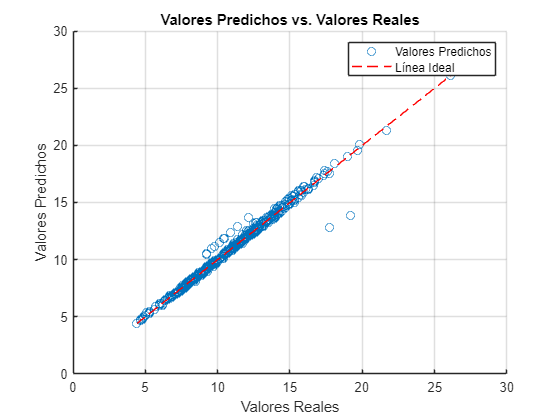

% Valores predichos vs. reales
Y_pred = predict(mdl, X);

figure;
scatter(Y, Y_pred);
title('Valores Predichos vs. Valores Reales');
xlabel('Valores Reales');
ylabel('Valores Predichos');
grid on;
hold on;
plot([min(Y) max(Y)], [min(Y) max(Y)], 'r--');
legend('Valores Predichos', 'Línea Ideal');
hold off;

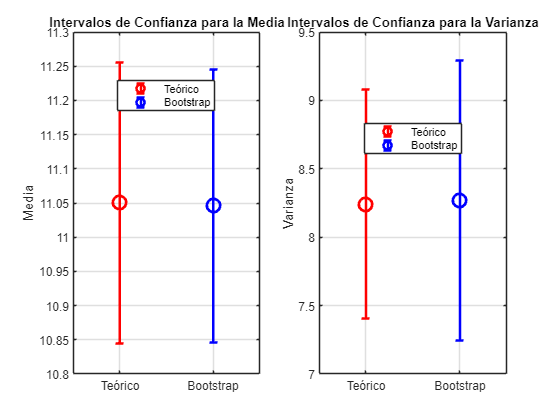

% Datos de los intervalos de confianza
CI_mu_teorico = [10.8449, 11.2559];
CI_mu_bootstrap = [10.8464, 11.2449];
CI_var_teorico = [7.4052, 9.0765];
CI_var_bootstrap = [7.2460, 9.2894];

% Valores centrales (medias y varianzas)
mu_teorico = mean(CI_mu_teorico);
mu_bootstrap = mean(CI_mu_bootstrap);
var_teorico = mean(CI_var_teorico);
var_bootstrap = mean(CI_var_bootstrap);

% Errores (mitad del intervalo)
error_mu_teorico = (CI_mu_teorico(2) - CI_mu_teorico(1)) / 2;
error_mu_bootstrap = (CI_mu_bootstrap(2) - CI_mu_bootstrap(1)) / 2;
error_var_teorico = (CI_var_teorico(2) - CI_var_teorico(1)) / 2;
error_var_bootstrap = (CI_var_bootstrap(2) - CI_var_bootstrap(1)) / 2;

% Datos para el gráfico de puntos
medias = [mu_teorico, mu_bootstrap];
errores_medias = [error_mu_teorico, error_mu_bootstrap];
varianzas = [var_teorico, var_bootstrap];
errores_varianzas = [error_var_teorico, error_var_bootstrap];

% Crear gráfico de puntos para la media
figure;
subplot(1, 2, 1);
errorbar(1, medias(1), errores_medias(1), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
hold on;
errorbar(2, medias(2), errores_medias(2), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
xlim([0.5 2.5]);
set(gca, 'XTick', 1:2, 'XTickLabel', {'Teórico', 'Bootstrap'});
ylabel('Media');
title('Intervalos de Confianza para la Media');
legend('Teórico', 'Bootstrap', 'Location', 'Best');
grid on;
hold off;

% Crear gráfico de puntos para la varianza
subplot(1, 2, 2);
errorbar(1, varianzas(1), errores_varianzas(1), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
hold on;
errorbar(2, varianzas(2), errores_varianzas(2), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
xlim([0.5 2.5]);
set(gca, 'XTick', 1:2, 'XTickLabel', {'Teórico', 'Bootstrap'});
ylabel('Varianza');
title('Intervalos de Confianza para la Varianza');
legend('Teórico', 'Bootstrap', 'Location', 'Best');
grid on;
hold off;